# Analyze hero usage from 1st week of OWL, seasons 1-3

This script will explore the the Stats Lab data provided the Overwatch League: [https://overwatchleague.com/en-us/statslab](https://overwatchleague.com/en-us/statslab). It will also look at the hero usage from the 1st week to see if season 3 had more or less variability in hero usage than seasons 1 and 2.

## Import data

The function `import_phs` used here was auto-generated by the Import Tool in MATLAB. The only change I made was to use utf-8 character encoding. I need that [umlaut](https://en.wikipedia.org/wiki/Germanic_umlaut) for Torbjörn.

phs2018_stage1 = import_phs("phs_2018\phs_2018_stage_1.csv");

## Explore data

The first thing I like to do is look at the table. In a Live Script, you can output a preview of the whole table and scroll through it by typing the name without a semicolon

But since this is meant to be a nicely formatted write-up, I'll use the `head` function to just print out the first 8 rows

head(phs2018_stage1)

ans = 8×10 table
       start_time       match_id    stage    map_type    map_name     player             team                 stat_name             hero       stat_amount
    ________________    ________    _____    ________    ________    _________    ___________________    ____________________    __________    ___________

    01/11/2018 00:12     10223        1      PAYLOAD      Dorado     Agilities    Los Angeles Valiant    All Damage Done         All Heroes       18079   
    01/11/2018 00:12     10223        1      PAYLOAD      Dorado     Agilities    Los Angeles Valiant    Assists                 All Heroes          17   
    01/11/2018 00:12  

So it looks like each row is a different statistic, identified by the `stat_name` column, with a corresponding value in `stat_amount`. The rest of the columns will have the identifying information like the date, match, player, map, hero, etc.

### Summarize columns

Another way to explore some new data is the `summary` function, which tries to give a short summary of each column. For categorical data with many categories (e.g. `player` or `stat_name`), it will print out the full list of categories, but it's still a good way to get a sense of the data.

phs_sample = phs2018_stage1(:,["start_time","hero"]);
summary(phs_sample)


Variables:

    start_time: 258758×1 datetime

        Values:

            Min       01/11/2018 00:12
            Median    01/27/2018 01:41
            Max       02/11/2018 05:51

    hero: 258758×1 categorical

        Values:

            All Heroes     64683 
            Ana             2934 
            Bastion         1278 
            D.Va           20757 
            Doomfist        1385 
            Genji          10983 
            Hanzo            902 
            Junkrat         9615 
            Lúcio           7951 
            McCree          7530 
            Mei              713 
            Mercy          16569 
            Moira           2155 
            Orisa           6464 
            Pharah          6242 
            Reaper          1431 
            Reinhardt       2068 
            Roadhog         7547 
            Soldier: 76     7647 
            Sombra          1535 
            Symmetra           9 
            Torbjörn

You can see the "All Heroes" category that sums together the stat values for each player. I'll need to remove these rows since I'm interested in breaking down the time by hero. Also, poor Symmetra. Only 9 entries in the whole first stage.

I'm purposefully not showing the output for `stat_name` because there are 253 different stats. But by looking through the full `summary` output, I found the "Time Played" statistic that I'll use to calculate play time for each hero.

### Which dates?

In order to get the first week, I need to know the dates. I can get quick sense of this by just plotting the data, which is already sorted by date.

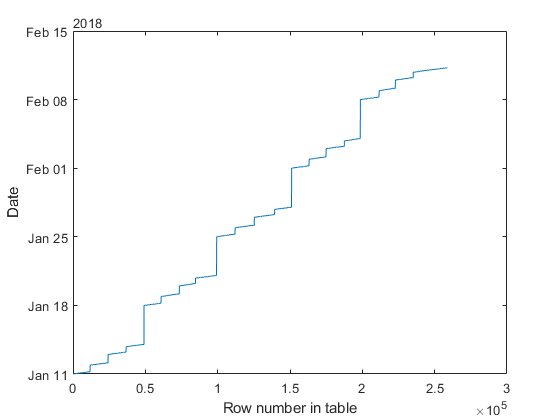

plot(phs2018_stage1.start_time)
xlabel("Row number in table")
ylabel("Date")

So the first week was from Jan 11 to Jan 14. I can use this to filter the table.

## Filter table

There are three filters, one each for `start_time`, `hero`, and `stat_name`.

isWeek1 = phs2018_stage1.start_time < "2018-01-15";
isHero = phs2018_stage1.hero ~= "All Heroes";
isTimePlayed = phs2018_stage1.stat_name == "Time Played";

I can use these to filter the table. I'll need to keep the columns for `hero` and `stat_amount`, which at this point will be only time played.

heroTable = phs2018_stage1(isWeek1 & isHero & isTimePlayed,["player","hero","stat_amount"]);
head(heroTable)

ans = 8×3 table
     player         hero       stat_amount
    _________    __________    ___________

    Agilities    Genji           836.33   
    Envy         D.Va            836.33   
    Fate         Winston         836.33   
    KariV        Mercy           836.33   
    SoOn         Tracer          750.68   
    SoOn         Widowmaker      85.657   
    uNKOE        Zenyatta        836.33   
    babybay      McCree          836.33   


Now the values in `stat_amount` are in seconds. MATLAB has a duration datatype that handles time values nicely, so I'll create a `timePlayed` column with duration values using the `seconds()` function.

Another nice thing I can do is change the formatting, so the duration values will be displayed with whatever format I want.

heroTable.timePlayed = seconds(heroTable.stat_amount);
heroTable.timePlayed.Format = "m";
head(heroTable)

ans = 8×4 table
     player         hero       stat_amount    timePlayed
    _________    __________    ___________    __________

    Agilities    Genji           836.33       13.939 min
    Envy         D.Va            836.33       13.939 min
    Fate         Winston         836.33       13.939 min
    KariV        Mercy           836.33       13.939 min
    SoOn         Tracer          750.68       12.511 min
    SoOn         Widowmaker      85.657       1.4276 min
    uNKOE        Zenyatta        836.33       13.939 min
    babybay      McCree          836.33       13.939 min


So now `timePlayed` is in minutes and I didn't have to bother with converting the values.

## Add up play time by hero

I can use the `groupsummary` function to add together `timePlayed` value in the table, grouped up by hero. 

results2018 = groupsummary(heroTable,"hero","sum","timePlayed")

results2018 = 25×3 table
      hero       GroupCount    sum_timePlayed
    _________    __________    ______________

    Ana              26          73.213 min  
    Bastion          12          43.318 min  
    D.Va             96          1050.3 min  
    Doomfist         16          19.514 min  
    Genji            55          337.59 min  
    Hanzo            16          30.386 min  
    Junkrat          48          267.12 min  
    Lúcio            73          172.34 min  
    McCree           51          179.28 min  
    Mei              10          9.3739 min  
    Mercy           110          1125.3 min  
    Moira            22          49.629 min  
    Orisa            33          185.06 min  
    Pharah           33          118.31 min  
    Reaper           16          61.517 min  
    Reinhardt        18          75.936 min  


The `GroupCount` column has the number of entries that contributed to the sum. Now I can clean up the results by renaming some things, as well as changing the format and sorting by most played

Now I'll clean up the results by sorting by most played and changing the display format to hours.

results2018 = sortrows(results2018,"sum_timePlayed","descend");
results2018.sum_timePlayed.Format = "h"

results2018 = 25×3 table
       hero        GroupCount    sum_timePlayed
    ___________    __________    ______________

    Mercy             110          18.754 hr   
    D.Va               96          17.505 hr   
    Winston            98          15.374 hr   
    Zenyatta           98          14.908 hr   
    Tracer            124          12.959 hr   
    Genji              55          5.6265 hr   
    Widowmaker         71          5.3826 hr   
    Junkrat            48           4.452 hr   
    Soldier: 76        67          3.3993 hr   
    Orisa              33          3.0843 hr   
    Roadhog            33           3.023 hr   
    McCree             51           2.988 hr   
    Lúcio              73          2.8724 hr   
    Pharah             33          1.9718 hr   
    Reinhardt          18          1.2656 hr   
    Ana                26          1.2202 hr   


Unsurprisingly, Mercy is the top played hero since this was right at the start of the Moth meta. Of course, a better way to display this data is visually in a bar graph.

bar(results2018.sum_timePlayed)
ylabel("Total Hours Played")
title("Hero play time, Week 1 2018")

I can clean up the x-axis by making sure each hero is labeled and the text rotated for visibility.

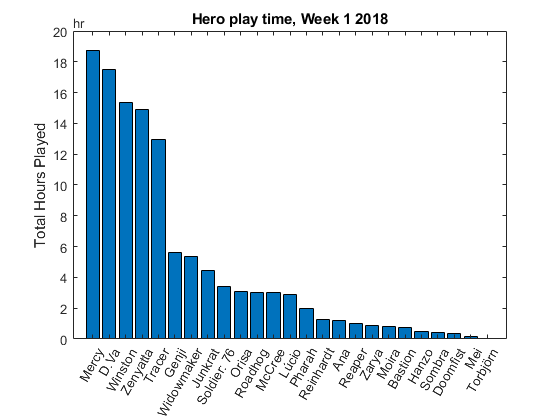

xticks(1:height(results2018))
xticklabels(results2018.hero)
xtickangle(60)
ylim(hours([0 20]))

Dive was clearly the meta for week 1 of the 2018 season with 5 heros dominating the play time: Mercy, D.Va, Winston, Zenyatta, and Tracer. The only variability was the last DPS, alternating between Genji, Widow, and Jakerat. No, that isn't a typo.

## Repeat for 2019

Now I can repeat the analysis for season 2. The only change in the code below is the different dates. For future analysis, I would put this code in a separate function for reuseability, but for now I'll copy/paste.

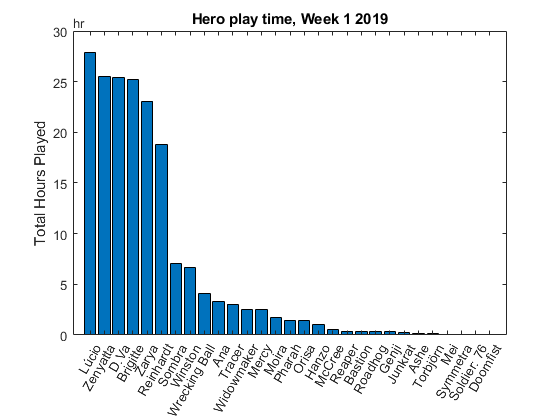

% Import data
phs2019_stage1 = import_phs("phs_2019\phs_2019_stage_1.csv");

% Filter table
isWeek1 = phs2019_stage1.start_time < "2019-02-19";
isHero = phs2019_stage1.hero ~= "All Heroes";
isTimePlayed = phs2019_stage1.stat_name == "Time Played";
heroTable = phs2019_stage1(isWeek1 & isHero & isTimePlayed,["player","hero","stat_amount"]);

% Create a duration variable with time played
heroTable.timePlayed = seconds(heroTable.stat_amount);
heroTable.timePlayed.Format = "h";

% Summarize play time
results2019 = groupsummary(heroTable,"hero","sum","timePlayed");
results2019 = sortrows(results2019,"sum_timePlayed","descend");

% Plot results
bar(results2019.sum_timePlayed)
ylabel("Total Hours Played")
title("Hero play time, Week 1 2019")
xticks(1:height(results2019))
xticklabels(results2019.hero)
xtickangle(60)
ylim(hours([0 30]))

GOATS GOATS GOATS

Season 2 was the season of GOATS up until the implementation of 2-2-2 in the final stage. So also unsurprisingly, the play time is dominated by the 6 GOAT heroes: Lúcio, Zenyatta, D.Va, Brigitte, Zarya, and Reinhardt. Sombra and Winston are a very distant 7th and 8th place. 

## Repeat for 2020

Yay now we can repeat for Season 3

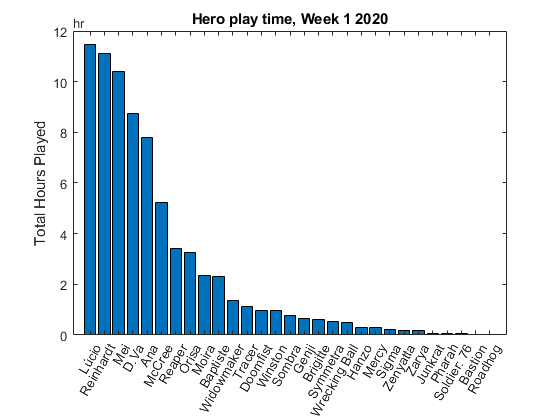

% Import data
phs2020_stage1 = import_phs2020("phs_2020\phs_2020_1.csv");

% Filter table
isWeek1 = phs2020_stage1.start_time < "2020-02-11";
isHero = phs2020_stage1.hero ~= "All Heroes";
isTimePlayed = phs2020_stage1.stat_name == "Time Played";
heroTable = phs2020_stage1(isWeek1 & isHero & isTimePlayed,["player","hero","stat_amount"]);

% Create a duration variable with time played
heroTable.timePlayed = seconds(heroTable.stat_amount);
heroTable.timePlayed.Format = "h";

% Summarize play time
results2020 = groupsummary(heroTable,"hero","sum","timePlayed");
results2020 = sortrows(results2020,"sum_timePlayed","descend");

% Plot results
bar(results2020.sum_timePlayed)
ylabel("Total Hours Played")
title("Hero play time, Week 1 2020")
xticks(1:height(results2020))
xticklabels(results2020.hero)
xtickangle(60)
ylim(hours([0 12]))

There are still some heroes that were played much more than others (Lucio, Reinhardt, and Mei), but to my eyes the transition from meta to non-meta is smoother (less of a sharp drop).

## Compare seasons

To compare the 3 seasons together, it may help to convert the hours played into a percentage, since each season had a different number of matches. To do so, I can divide each hero's total by the total time played across all matches.

results2018.percentPlayed = results2018.sum_timePlayed/sum(results2018.sum_timePlayed)*100

results2018 = 25×4 table
       hero        GroupCount    sum_timePlayed    percentPlayed
    ___________    __________    ______________    _____________

    Mercy             110          18.754 hr          15.664    
    D.Va               96          17.505 hr          14.621    
    Winston            98          15.374 hr          12.841    
    Zenyatta           98          14.908 hr          12.452    
    Tracer            124          12.959 hr          10.823    
    Genji              55          5.6265 hr          4.6994    
    Widowmaker         71          5.3826 hr          4.4957    
    Junkrat            48           4.452 hr          3.7184    
    Soldier: 76        67          3.3993 hr          2.8392    
    Orisa              33          3.0843 hr          2.5761    
    Roadhog            33           3.023 hr          2.52

Repeat for the 2019 and 2020 seasons

% 2019 season
results2019.percentPlayed = results2019.sum_timePlayed/sum(results2019.sum_timePlayed)*100;

% 2020 season
results2020.percentPlayed = results2020.sum_timePlayed/sum(results2020.sum_timePlayed)*100;

Now I can compare these three sets of data on the same axis

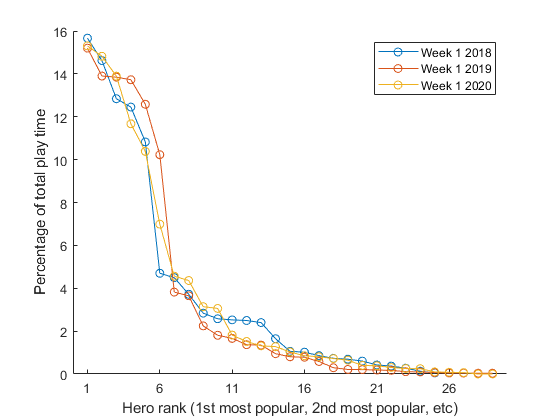

figure; hold on;
plot(results2018.percentPlayed,'o-')
plot(results2019.percentPlayed,'o-')
plot(results2020.percentPlayed,'o-')
hold off
xlabel("Hero rank (1st most popular, 2nd most popular, etc)")
ylabel("Percentage of total play time")
xticks(1:5:30)
legend(["Week 1 2018","Week 1 2019","Week 1 2020"])

## How strong is the meta?

### Method 1: Percentage of time played by top 6 heroes

There are many ways I could try to quantify the strength of the meta, but one is calculating the percentage of time played by heroes that are in the top 6. I'll organize the results in a table.

% Add together the percentage from heroes ranked 1 to 6
Year = [2018; 2019; 2020];
percentTop6 = [sum(results2018.percentPlayed(1:6)); ...
    sum(results2019.percentPlayed(1:6)); ...
    sum(results2020.percentPlayed(1:6))];

% Add variables to a table
metaStrength = table(Year,percentTop6)

metaStrength = 3×2 table
    Year    percentTop6
    ____    ___________

    2018        71.1   
    2019      79.488   
    2020      73.072   


So in 2018, 71.1% of the total time played was from the six most played heroes, i.e. Mercy, D.Va, Winston, Zenyatta, Tracer, and Genji. The percentage is higher in 2019, where the GOATS meta was very strong.

Interestingly, the 2020 value is a bit higher than 2018, indicating it may have had a slightly stronger meta (at least the first week).

### Method 2: Logistic function fit

The percentage is a decent measure, but it doesn't capture how "sharp" the dropoff is between the top 6 heroes and the rest of the pack. So, I'll try a different method by trying to fit the data with a logistic function and look at the decay rate. 

#### Discussion of fits

A simple logistic function has the form:


$$f(x) = \frac{1}{1+e^{-x}}$$


We can see the shape with `fplot()`.

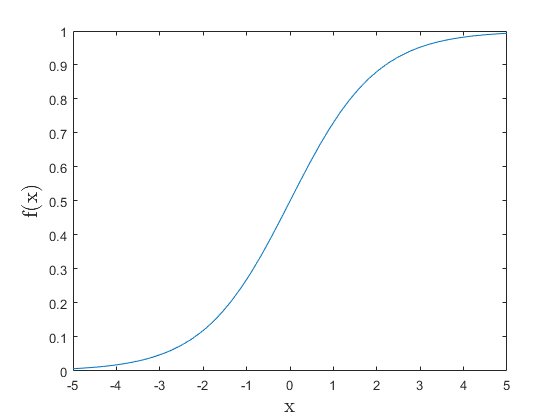

f = @(x) 1./(1+exp(-x));
figure
fplot(f,[-5 5])
xlabel("x","Interpreter","latex","FontSize",16)
ylabel("f(x)","Interpreter","latex","FontSize",16)

To fit my data, we'll set a free parameter that will flip the curve horizontally (so that it starts high drops off) and define how fast it changes. The general form will be:


$$f(x) = \frac{16.667}{1+e^{B(x-6)}$$


The $16.667$ in the denominator is sort of a theoretical maximum. If only 6 heroes are played, then all their percentages will be 100/6 = 16.667. The $x-6$ in the exponent will shift the curve so the point of inflection is at $x=6$, which is what we would expect for a perfectly strict meta (only 6 heroes played, with all other heroes at 0%. The free parameter $B$ will control the sharpness of the transition. Here's the plot for a few values of $B$.

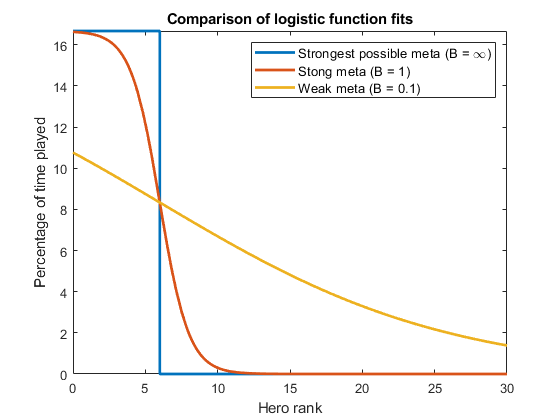

% Define three logistic curves
fSharp = @(x) 16.667./(1+exp(inf*(x-6)));
fMed = @(x) 16.667./(1+exp(1*(x-6)));
fShallow = @(x) 16.667./(1+exp(0.1*(x-6)));

% Plot curves
figure
fplot(fSharp,[0 30],"LineWidth",2)
hold on
fplot(fMed,[0 30],"LineWidth",2)
fplot(fShallow,[0 30],"LineWidth",2)
hold off
legend(["Strongest possible meta (B = \infty)","Stong meta (B = 1)", ...
    "Weak meta (B = 0.1)"],"FontSize",10)
xlabel("Hero rank")
ylabel("Percentage of time played")
title("Comparison of logistic function fits")

You can see that the value of $B$ from the fit will be a measure of the strength of the meta.

#### Apply fits to data

Now I can apply this fit to the data to get the value of $B$. From here on, I'll refer to $B$ as the "meta sharpness".

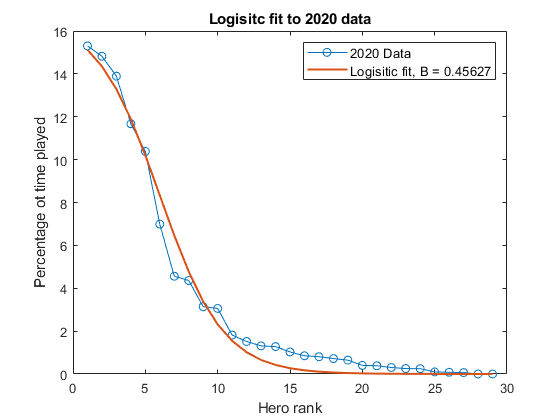

% Set up fittype
fitObject = fittype("16.667/(1+exp(B*(x-6)))");

% Apply fit
x = (1:height(results2020))';
y = results2020.percentPlayed;
fitResult2020 = fit(x,y,fitObject,"StartPoint",1,"Display","off");

% Plot fit
figure
plot(x,y,'o-')
hold on
plot(x,fitResult2020(x),'Linewidth',1.5)
hold off
legend(["2020 Data","Logisitic fit, B = " + fitResult2020.B],"FontSize",10)
xlabel("Hero rank")
ylabel("Percentage ot time played")
title("Logisitc fit to 2020 data")

The fit is pretty good, at least for 2020. And it yields a value of $B = 0.4563$, which can be compared with the 2018 and 2019 values. 

% 2018 fit
x = (1:height(results2018))';
y = results2018.percentPlayed;
fitResult2018 = fit(x,y,fitObject,"StartPoint",1,"Display","off");

% 2019 fit
x = (1:height(results2019))';
y = results2019.percentPlayed;
fitResult2019 = fit(x,y,fitObject,"StartPoint",1,"Display","off");

% Add fit values to metaStrength table. Label as "sharpness"
metaStrength.Sharpness = [fitResult2018.B; ...
    fitResult2019.B; ...
    fitResult2020.B]

metaStrength = 3×3 table
    Year    percentTop6    Sharpness
    ____    ___________    _________

    2018        71.1        0.43937 
    2019      79.488        0.59113 
    2020      73.072        0.45627 


The two measures agree at least in terms of which years have the highest values.

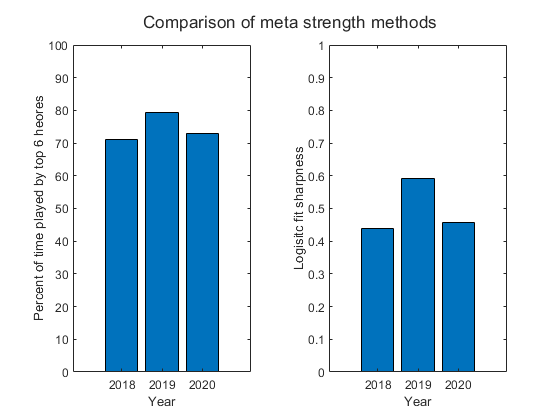

% Compare values in two bar plots
figure
tl = tiledlayout(1,2);
nexttile
bar(metaStrength.Year,metaStrength.percentTop6)
xlabel("Year")
ylabel("Percent of time played by top 6 heores")
ylim([0 100])

nexttile
bar(metaStrength.Year,metaStrength.Sharpness)
xlabel("Year")
ylabel("Logisitc fit sharpness")
ylim([0 1])
title(tl,"Comparison of meta strength methods")

Relatively speaking, it looks like the sharpness is a more sensitive measure. It also looks like the first week of the 2020 season didn't have *that* much more hero variety, at least compared to 2018.

## Bring it all together: week by week analysis for 2018

The real interesting thing will be to see how these measures evolved over time in 2018 and 2019. To find out, I'll have to combine the data across years and stages.

To import the data, I'll use a datastore, which will allow me to import all the data at once for a year

ds = fileDatastore("phs_2018\phs_2018*.csv","ReadFcn",@import_phs,"UniformRead",true);
phs2018 = readall(ds);
phs2018 = sortrows(phs2018,"start_time","ascend");
head(phs2018)

ans = 8×10 table
       start_time       match_id    stage    map_type    map_name     player             team                 stat_name             hero       stat_amount
    ________________    ________    _____    ________    ________    _________    ___________________    ____________________    __________    ___________

    01/11/2018 00:12     10223        1      PAYLOAD      Dorado     Agilities    Los Angeles Valiant    All Damage Done         All Heroes       18079   
    01/11/2018 00:12     10223        1      PAYLOAD      Dorado     Agilities    Los Angeles Valiant    Assists                 All Heroes          17   
    01/11/2018 00:12  

This is a big table but I can use `groupsummary` to calculate the same values as before. First, I need to create a "week" variable, since the data currently only separate the data into stages.

### Create the week variable for 2018

First I'll use the date and time of each match to get the week in which each entry occurred. This involves using `dateshift` to shift the datetime values in order to group the entires.

% Create a datetime array with the match start times shifted to the 
% previous Wednesday. Matches for each week started on Thursday
shiftedStart = dateshift(phs2018.start_time,"dayofweek","Wednesday","previous");

% Round the times to the previous midnight (this creates duplicate entries)
% and convert to a categorical array
phs2018.weekName = categorical(dateshift(shiftedStart,"start","day"),"Ordinal",true);

Next, convert the category names from the datetime value to something more readable, e.g. `"01/20/2018 00:00"` will become `"Stage 1, Week 1"`.

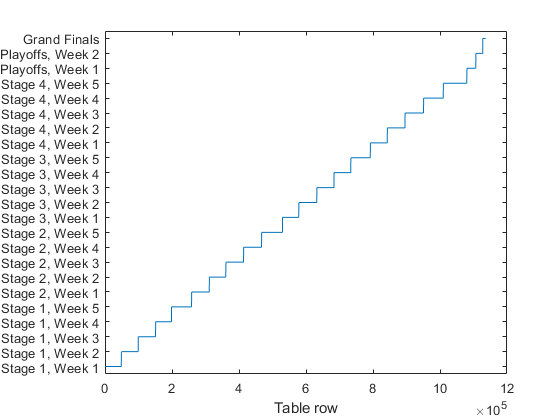

% Get list of old and new categories
oldCategories = categories(phs2018.weekName);
stages = groupsummary(phs2018,["stage","weekName"]).stage;
newCategories = "Stage " + stages(1:end-3) + ", Week " + repmat((1:5)',4,1);
newCategories(end+1:end+3) = ["Playoffs, Week " + (1:2)'; "Grand Finals"];
phs2018.weekName = renamecats(phs2018.weekName,oldCategories,newCategories);

% Plot the new "weekName" variable
figure
plot(phs2018.weekName)
xlabel("Table row")

### Get weekly measures of meta strength

I'll calculate the same measures of meta strength as before, i.e. the percentage of time played by the top 6 heroes and the meta "sharpness"

% Filter table
isTimePlayed = phs2018.stat_name == "Time Played";
isHero = phs2018.hero ~= "All Heroes";
heroTable = phs2018(isHero & isTimePlayed,["weekName","hero","stat_amount"]);

% Summarize play time
all2018 = groupsummary(heroTable,["hero","weekName"],"sum","stat_amount");
all2018 = sortrows(all2018,["weekName","sum_stat_amount"],["ascend","descend"]);
head(all2018)

ans = 8×4 table
       hero          weekName        GroupCount    sum_stat_amount
    __________    _______________    __________    _______________

    Mercy         Stage 1, Week 1       110             67516     
    D.Va          Stage 1, Week 1        96             63019     
    Winston       Stage 1, Week 1        98             55346     
    Zenyatta      Stage 1, Week 1        98             53671     
    Tracer        Stage 1, Week 1       124             46651     
    Genji         Stage 1, Week 1        55             20255     
    Widowmaker    Stage 1, Week 1        71             19377     
    Junkrat       Stage 1, Week 1        48             16027     


You can see the above table has a row for each week and hero. In order to get a single row for each week, I can "unstack" the hero column, which creates a column for each hero.

all2018 = unstack(all2018(:,["hero","weekName","sum_stat_amount"]), ...
    "sum_stat_amount","hero");

head(all2018(:,1:6))

ans = 8×6 table
       weekName         Ana      Bastion    Brigitte    D_Va     Doomfist
    _______________    ______    _______    ________    _____    ________

    Stage 1, Week 1    4392.8    2599.1       NaN       63019     1170.9 
    Stage 1, Week 2    2957.3    1822.6       NaN       66330     569.67 
    Stage 1, Week 3    2187.6    1697.7       NaN       69159     422.33 
    Stage 1, Week 4    2072.6    1293.7       NaN       69303     1945.9 
    Stage 1, Week 5    1675.7    1072.3       NaN       87511      593.1 
    Stage 2, Week 1     11260    21.403       NaN       73840     870.26 
    Stage 2, Week 2     10034    203.39       NaN       67495     551.14 
    Stage 2, Week 3     11161    132.36       NaN       78643     1126.1 


This table has a lot columns, so I'm only showing the first 6. The last steps before calculating the meta strength is replacing the NaN values with zeros (these are from weeks before Brigitte was in the game), as well as convert from seconds played to percentage of total time played.

all2018 = fillmissing(all2018,"constant",0,"DataVariables",2:size(all2018,2));
all2018{:,2:end} = all2018{:,2:end} ./ sum(all2018{:,2:end},2)*100;
head(all2018(:,1:6))

ans = 8×6 table
       weekName          Ana       Bastion     Brigitte     D_Va     Doomfist
    _______________    _______    _________    ________    ______    ________

    Stage 1, Week 1     1.0192      0.60301       0        14.621     0.27165
    Stage 1, Week 2    0.66305      0.40864       0        14.872     0.12772
    Stage 1, Week 3    0.44345      0.34414       0        14.019    0.085612
    Stage 1, Week 4    0.45731      0.28545       0        15.291     0.42934
    Stage 1, Week 5    0.29774      0.19053       0        15.549     0.10538
    Stage 2, Week 1     2.3884    0.0045397       0        15.662     0.18459
    Stage 2, Week 2     2.3463     0.047562       0        15.783     0.12888
    Stage 2, Week 3     2.3036     0.027318       0        16.231     0.23242

To calculate the measures of meta stength, I copied the code from above into separate functions named `sumTop6` and `fitLogistic`. These can be used with `rowfun` to apply the functions to each row. 

% Apply our two measures with rowfun
all2018.percentTop6 = rowfun(@sumTop6,all2018(:,2:end), ...
    "SeparateInputs",false,"OutputFormat","uniform");
all2018.sharpness = rowfun(@fitLogistic,all2018(:,2:end), ...
    "SeparateInputs",false,"OutputFormat","uniform");
metaStrength2018 = all2018(:,["weekName","percentTop6","sharpness"]);
head(metaStrength2018)

ans = 8×3 table
       weekName        percentTop6    sharpness
    _______________    ___________    _________

    Stage 1, Week 1        71.1        0.99793 
    Stage 1, Week 2      72.779         1.0424 
    Stage 1, Week 3      72.682        0.99939 
    Stage 1, Week 4      74.837         1.1004 
    Stage 1, Week 5      75.058         1.0505 
    Stage 2, Week 1      74.051          1.001 
    Stage 2, Week 2      72.085        0.99892 
    Stage 2, Week 3      72.328        0.97325 


### Visualize results together

Below I plot both measure on the same axis using `yyaxis`. I'm not a huge fan of these types of plots because they are very easy to manipulate to say whatever you want by manipulating the two axes limits. However, when the axes span the full range of the data, this type of plot is decent for getting a rough sense for how correlated the lines are.

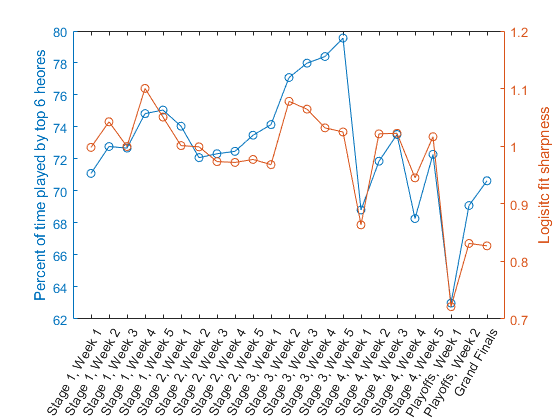

figure
yyaxis left
plot(all2018.percentTop6,'o-')
ylabel("Percent of time played by top 6 heores")

yyaxis right
plot(all2018.sharpness,'o-')
ylabel("Logisitc fit sharpness")

xticks(1:height(all2018))
xticklabels(all2018.weekName)
xtickangle(60)
xlim([0 height(all2018)+1])

I can also calculate the correlation coefficent between the measures.

corr(all2018.percentTop6,all2018.sharpness)

ans = 0.8085

A positive value near 1 indicates a strong positive correlation between the two measures. This means the measueres tend to go up and down together. 

## Repeat week by week analysis for 2019

Repeat the previous steps with another datastore, this time with the 2019 data.

ds = fileDatastore("phs_2019\phs_2019*.csv","ReadFcn",@import_phs,"UniformRead",true);
phs2019 = readall(ds);
phs2019 = sortrows(phs2019,"start_time","ascend");
head(phs2019)

ans = 8×10 table
       start_time       match_id    stage    map_type    map_name    player         team               stat_name             hero       stat_amount
    ________________    ________    _____    ________    ________    ______    _______________    ____________________    __________    ___________

    02/15/2019 00:11     21211        1      CONTROL      Ilios      Bdosin    London Spitfire    All Damage Done         All Heroes       14845   
    02/15/2019 00:11     21211        1      CONTROL      Ilios      Bdosin    London Spitfire    Assists                 All Heroes          13   
    02/15/2019 00:11     21211        1      CONTR

Create the "weekName" variable. This is a bit more complicated in 2019 because the stage playoffs were on separate weeks.

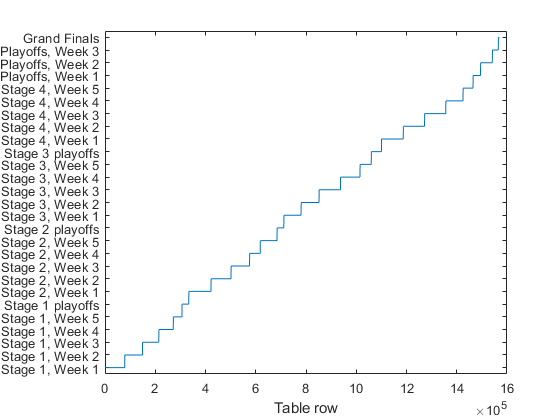

% Create a categorical variable for week
shiftedStart = dateshift(phs2019.start_time,"dayofweek","Wednesday","previous");
phs2019.weekName = categorical(dateshift(shiftedStart,"start","day"),"Ordinal",true);

% Rename categories
oldCategories = categories(phs2019.weekName);
stages = groupsummary(phs2019,["stage","weekName"]).stage;
newCategories = "Stage " + stages(1:end-4) + ", Week " + [repmat((1:6)',3,1); (1:5)'];
newCategories([6,12,18]) = "Stage " + (1:3)' + " playoffs";
newCategories(end+1:end+4) = ["Playoffs, Week " + (1:3)'; "Grand Finals"];
phs2019.weekName = renamecats(phs2019.weekName,oldCategories,newCategories);

% Plot the new "weekName" variable
figure
plot(phs2019.weekName)
xlabel("Table row")

Apply the same functions to the data to calculate the meta strength

% Filter table
isTimePlayed = phs2019.stat_name == "Time Played";
isHero = phs2019.hero ~= "All Heroes";
heroTable = phs2019(isHero & isTimePlayed,["weekName","hero","stat_amount"]);

% Summarize play time
all2019 = groupsummary(heroTable,["hero","weekName"],"sum","stat_amount");
all2019 = sortrows(all2019,["weekName","sum_stat_amount"],["ascend","descend"]);
all2019 = unstack(all2019(:,["hero","weekName","sum_stat_amount"]), ...
    "sum_stat_amount","hero");


% Replace NaN with zeros and calucate percentage
all2019 = fillmissing(all2019,"constant",0,"DataVariables",2:size(all2019,2));
all2019{:,2:end} = all2019{:,2:end} ./ sum(all2019{:,2:end},2)*100;

% Apply our two measures with rowfun
all2019.percentTop6 = rowfun(@sumTop6,all2019(:,2:end), ...
    "SeparateInputs",false,"OutputFormat","uniform");
all2019.sharpness = rowfun(@fitLogistic,all2019(:,2:end), ...
    "SeparateInputs",false,"OutputFormat","uniform");
metaStrength2019 = all2019(:,["weekName","percentTop6","sharpness"]);
head(metaStrength2019)

ans = 8×3 table
        weekName        percentTop6    sharpness
    ________________    ___________    _________

    Stage 1, Week 1       79.488        0.97451 
    Stage 1, Week 2       83.997         1.0115 
    Stage 1, Week 3       89.853         1.0961 
    Stage 1, Week 4       89.296         1.0856 
    Stage 1, Week 5       87.879          1.039 
    Stage 1 playoffs      94.039         1.1368 
    Stage 2, Week 1       58.363        0.66797 
    Stage 2, Week 2       70.796        0.84696 


Compare the two measures in a `yyaxis` plot

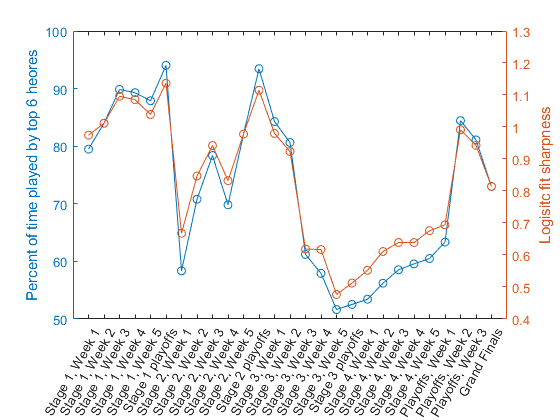

figure
yyaxis left
plot(all2019.percentTop6,'o-')
ylabel("Percent of time played by top 6 heores")
ylim([50 100])

yyaxis right
plot(all2019.sharpness,'o-')
ylabel("Logisitc fit sharpness")
%ylim([0.5 1.5])

xticks(1:height(all2019))
xticklabels(all2019.weekName)
xtickangle(60)
xlim([0 height(all2019)+1])

If you compare the y-axis range on this plot to the 208 plot, you'll see that the 2019 data has a much large range. This will be easier to see when I put the data on the same set of axes.

Also, the correlation coefficient is even higher for 2019.

corr(all2019.percentTop6,all2019.sharpness)

ans = 0.9920

## Putting both seasons on the same plot

Phew, this script became too long like 7 sections ago. But this is the very last one. I'll compare the two years by putting both years on the same graph.

Since the two measures are highly correlated, I'll just visualize the simpler measure of `percentTop6`. 

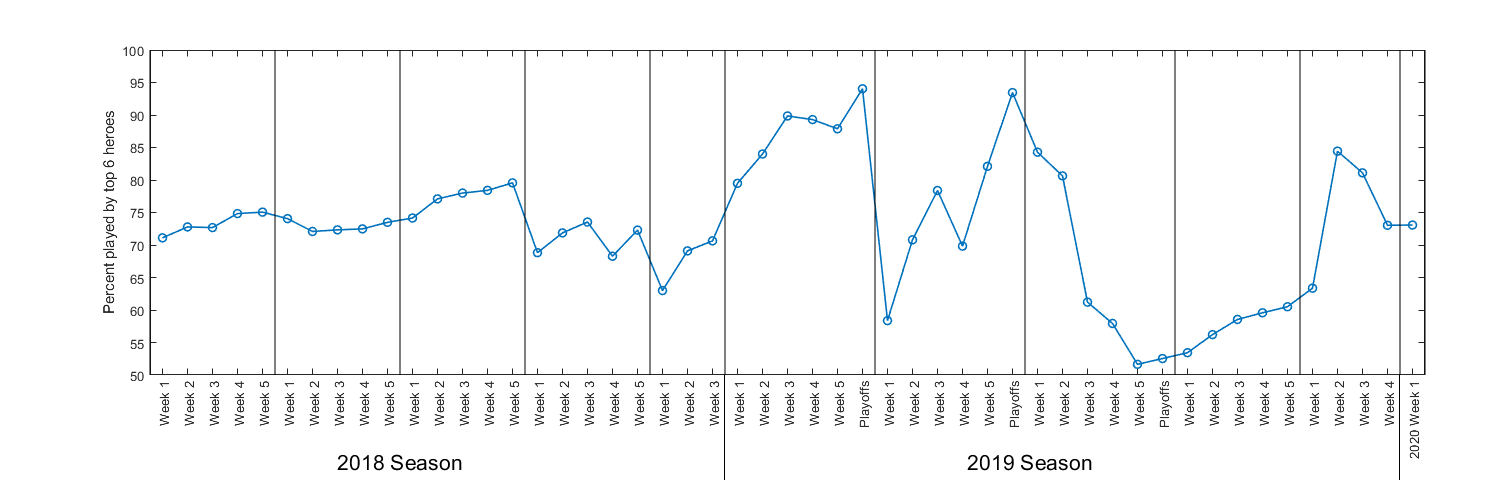

% Combine data together and plot as a line
fig = figure("Name","AllYears","Color","w","Position",[100 400 1500 500], ...
    "Visible","on","PaperSize",[24 11]);
data = [all2018.percentTop6; all2019.percentTop6; ...
    metaStrength.percentTop6(end)];
plot(data,"o-","LineWidth",1.2)

% Change a ton of axes parameters to label the data
% Also add lines to mark the stages apart
ax = gca;
ax.YLabel.String = "Percent played by top 6 heroes";
ax.XLim = 0.5 + [0 length(data)];
stagePoints = [0 5 10 15 20 23 29 35 41 46 50 51];
line(stagePoints + [0.5;0.5], zeros(2,length(stagePoints)) ...
    + [50;100],"Color","k","LineWidth",0.5)
ax.XTick = 1:length(data);
ax.XTickLabel = ["Week " + repmat(1:5,1,4), ...
    "Week " + (1:3), ...
    repmat(["Week " + (1:5),"Playoffs"],1,3), ...
    "Week " + (1:5), ...
    "Week " + (1:4), ...
    "2020 Week 1"];
ax.XTickLabelRotation = 90;
ax.Position = [0.1 0.25 0.85 0.65];
ax.TickLength = [0.005,0.01];

% Add a couple annotations. This type of thing is easier to do 
% in Inkscape or Adobe Illustrator.
annotation(fig,"line",[0.483 0.483],[0.25 0.04]);
annotation(fig,"line",[0.933 0.933],[0.25 0.04]);
annotation(fig,"textbox",...
    [0.22 0.052 0.14 0.06],...
    "String","2018 Season",...
    "FontSize",16,...
    "EdgeColor","none");
annotation(fig,"textbox",[0.64 0.052 0.14 0.06], ...
    "String","2019 Season",...
    "FontSize",16,...
    "EdgeColor","none");

I think there are several interesting trends here:

- The meta in 2018 was much more stable than in 2019 with the GOATS meta. In the 2019 Stage 1 playoffs, GOATS heroes were played 94% of the time. But in the Stage 3 playoffs, the top 6 heroes were played only 52% of the time. This was perhaps my favorite week in all of OWL, when the Shanghai Dragons upset both the San Francisco Shock and Vancouver Titans with their 3 DPS, 2 healer, 1 tank lineup.

- GOATS was already dying before 2-2-2 was introduced. Not only was Sombra being played more, but 3 DPS lineups were popular. As I mentioned earlier though, it's likely that the mere threat of 2-2-2 was affecting hero choices at this point.

To wrap up, it appears that the start of the 2020 season is average in terms of the strength of the meta. I'm excited to see how it changes with Hero Pools, and I hope Blizzard keeps trying to make the meta interesting to watch (and maybe to play, too).